# Electricity Usage Difference Between 1990 and 2019

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

electricity = readtable("../data/electricity.csv"); 

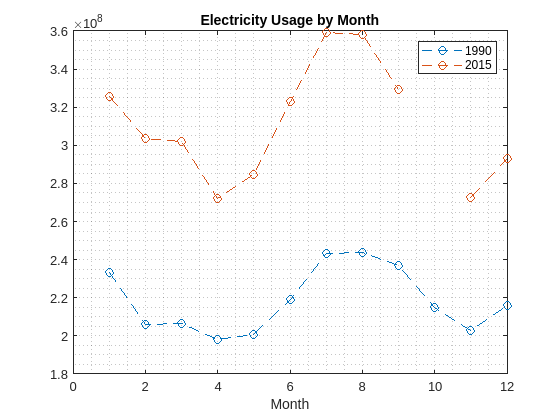

electricity = electricity(1:find(electricity.Date=='12/01/2015'), :);
com = reshape(electricity.Commercial, 12, []);
res = reshape(electricity.Residential, 12, []);
ind = reshape(electricity.Industrial, 12, []);

usage = ind + res + com;
firstYear = usage(:, 1);
lastYear = usage(:, end);
plot(1:12, firstYear, "o--")
hold on
grid minor
plot(1:12, lastYear, "o--")
hold off
title("Electricity Usage by Month")
legend("1990", "2015")
xlabel("Month")

usageDiff = lastYear - firstYear;

## Task 1

[maxUsage,monthNum] = max(usageDiff)

maxUsage = 116266409

monthNum = 7

## Task 2

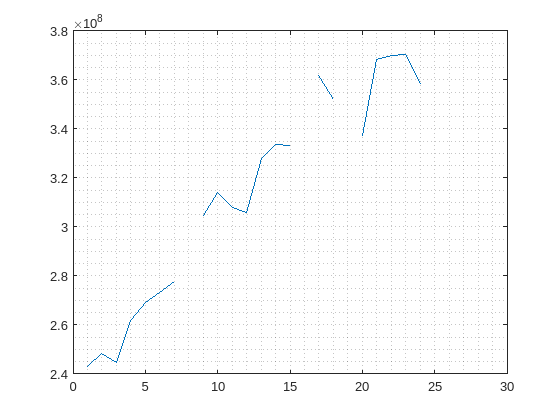

july = usage(monthNum, :);
plot(july)
grid minor

## Task 3

[diffSorted,sortedIdx] = sort(usageDiff, "descend")

diffSorted =          NaN
   116266409
   114640651
   103625082
    97786607
    95321710
    92607212
    92303199
    84147723
    77497328


sortedIdx =     10
     7
     8
     6
     2
     3
     1
     9
     5
    12
